syms x(t) y(t)

A = [1 2; -1 1];
B = [1; t];
Y = [x; y];
odes = diff(Y) == A*Y + B 

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=x\left(t\right)+2\,y\left(t\right)+1\\ \frac{\partial }{\partial t}y\left(t\right)=t-x\left(t\right)+y\left(t\right) \end{array}\right)$$

[xSol(t ), ySol(t )] = dsolve(odes);
xSol(t ) = simplify(xSol(t))

$$xSol(t) = \frac{2\,t}{3}+\sqrt{2}\,C_{2}\,{\mathrm{e}}^{t}\,\cos\left(\sqrt{2}\,t\right)+\sqrt{2}\,C_{1}\,{\mathrm{e}}^{t}\,\sin\left(\sqrt{2}\,t\right)+\frac{1}{9}$$

ySol(t) = simplify(ySol(t))

$$ySol(t) = C_{1}\,{\mathrm{e}}^{t}\,\cos\left(\sqrt{2}\,t\right)-\frac{t}{3}-C_{2}\,{\mathrm{e}}^{t}\,\sin\left(\sqrt{2}\,t\right)-\frac{2}{9}$$


c = Y(0) == [2; -1];
[xSol(t), ySol(t)] = dsolve(odes, c)

$$xSol(t) = \begin{array}{l} \sqrt{2}\,{\mathrm{e}}^{t}\,\sigma_{2}\,\left(\frac{17\,\sqrt{2}}{18}+\frac{{\mathrm{e}}^{-t}\,\left(4\,\sigma_{1}+\sqrt{2}\,\sigma_{2}+6\,t\,\sigma_{1}+6\,\sqrt{2}\,t\,\sigma_{2}\right)}{18}\right)-\sqrt{2}\,{\mathrm{e}}^{t}\,\sigma_{1}\,\left(\frac{{\mathrm{e}}^{-t}\,\left(4\,\sigma_{2}-\sqrt{2}\,\sigma_{1}+6\,t\,\sigma_{2}-6\,\sqrt{2}\,t\,\sigma_{1}\right)}{18}+\frac{7}{9}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\sqrt{2}\,t\right)\\ \sigma_{2}=\cos\left(\sqrt{2}\,t\right) \end{array}$$

$$ySol(t) = \begin{array}{l} -{\mathrm{e}}^{t}\,\sigma_{1}\,\left(\frac{17\,\sqrt{2}}{18}+\frac{{\mathrm{e}}^{-t}\,\left(4\,\sigma_{1}+\sqrt{2}\,\sigma_{2}+6\,t\,\sigma_{1}+6\,\sqrt{2}\,t\,\sigma_{2}\right)}{18}\right)-{\mathrm{e}}^{t}\,\sigma_{2}\,\left(\frac{{\mathrm{e}}^{-t}\,\left(4\,\sigma_{2}-\sqrt{2}\,\sigma_{1}+6\,t\,\sigma_{2}-6\,\sqrt{2}\,t\,\sigma_{1}\right)}{18}+\frac{7}{9}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\sqrt{2}\,t\right)\\ \sigma_{2}=\cos\left(\sqrt{2}\,t\right) \end{array}$$

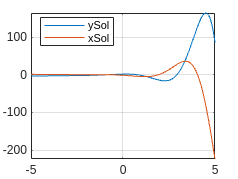


fplot(xSol)
hold on
fplot(ySol)
grid on
legend("ySol", "xSol", Location="best")